clear;
H = dvbs2ldpc(1/2)

H = 32400x64800 sparse logical array (226799 nonzeros)
        (55,1)            1
      (2535,1)            1
      (8598,1)            1
      (9319,1)            1
     (10220,1)            1
     (14393,1)            1
     (26910,1)            1
     (27562,1)            1
       (145,2)            1
      (2625,2)            1
      (8688,2)            1
      (9409,2)            1
     (10310,2)            1
     (14483,2)            1
     (27000,2)            1
     (27652,2)            1
       (235,3)            1
      (2715,3)            1
      (8778,3)            1
      (9499,3)            1
     (10400,3)            1
     (14573,3)            1
     (27090,3)            1
     (27742,3)            1
       (325,4)            1
      (2805,4)            1
      (8868,4)            1
      (9589,4)            1
     (10490,4)            1
     (14663,4)            1
     (27180,4)            1
     (27832,4)            1
       (415,5)            1
      (2895,5)       

cfgLDPCEnc = ldpcEncoderConfig(H)

cfgLDPCEnc =   ldpcEncoderConfig with properties:

     ParityCheckMatrix: [32400x64800 logical]

   Read-only properties:
           BlockLength: 64800
    NumInformationBits: 32400
    NumParityCheckBits: 32400
              CodeRate: 0.5000


numframes = 1;
cfgLDPCDec = ldpcDecoderConfig(H)

cfgLDPCDec =   ldpcDecoderConfig with properties:

     ParityCheckMatrix: [32400x64800 logical]
             Algorithm: 'bp'

   Read-only properties:
           BlockLength: 64800
    NumInformationBits: 32400
    NumParityCheckBits: 32400
              CodeRate: 0.5000


n = cfgLDPCEnc.NumInformationBits;
BlockLengthHalf = cfgLDPCDec.BlockLength/2

BlockLengthHalf = 32400

K = 20; % Number of codewords to process
LdpcErr_2=[]


LdpcErr_2 =

     []



place=zeros(1,20);
for snr=1:0.3:3
    error=zeros(1,1000);
    for k=1:1000
        for j=1:K
            data{j} = randi([0 1],n,numframes,'int8');
        end
        for j=1:K
            codedData{j} = Code(data{j},cfgLDPCEnc);
            cD1{j}=reshape(codedData{j},[2 BlockLengthHalf])';
        end
        input=pskmod(cD1{1}(:,1),2,0);
        for j=1:K-1
            input1 = bi2de([cD1{j}(:,2),cD1{j+1}(:,1)],"left-msb");
            input = [input;pskmod(input1,4,pi/4)];
        end
        input = [input;pskmod(cD1{K}(:,2),2,0)];
        output = awgn(input,snr);
        for j=1:K-1
            LLR1Half{j} = pskdemod(output(BlockLengthHalf*(j-1)+1:BlockLengthHalf*j),2,0,OutputType="llr");
            LLR2Half = reshape(pskdemod(output(BlockLengthHalf*j+1:BlockLengthHalf*(j+1)),4,pi/4,OutputType="llr"),[2 BlockLengthHalf])';
            LLR{j} = [LLR1Half{j},LLR2Half(:,1)];
            LlrActual=LLR{j}';
            decodedData{j} = Decode(LlrActual(:),cfgLDPCDec);
            EstimatedCodeword = Code(decodedData{j},cfgLDPCEnc);
            EstimatedCodeword = reshape(EstimatedCodeword,[2 BlockLengthHalf])';
            SecondPartECWinFourier = pskmod(EstimatedCodeword(:,2),2,pi/2);
            output(BlockLengthHalf*j+1:BlockLengthHalf*(j+1))=output(BlockLengthHalf*j+1:BlockLengthHalf*(j+1))-1/sqrt(2)*SecondPartECWinFourier;    
        end
        LLR{K} = reshape(pskdemod(output(BlockLengthHalf*(20-1)+1:BlockLengthHalf*(20+1)),2,0,OutputType="llr"),[BlockLengthHalf 2]);
        LlrActual=LLR{K}';
        decodedData{K} = Decode(LlrActual(:),cfgLDPCDec);
        for j=1:K
            ErrCount(j)=biterr(data{j},decodedData{j});
        end
        error(k)=sum(ErrCount)/K;
        if ErrCount ~= 0
            [m,j]=max(ErrCount);
            place(j)=place(j)+1;
        end
    end
    LdpcErr_2(end+1)=mean(error)/n;
    snr
end

snr = 1

snr = 1.3000

snr = 1.6000

snr = 1.9000

snr = 2.2000

snr = 2.5000

snr = 2.8000

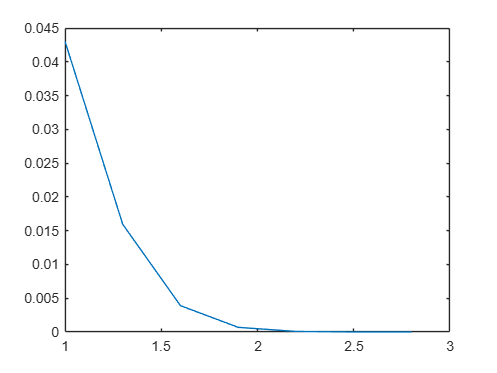

plot(1:0.3:3,LdpcErr_2)

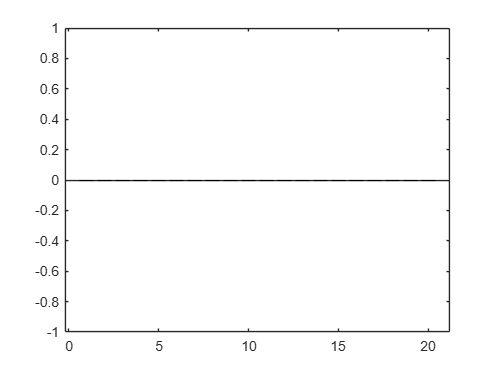

bar(place)


function output=Code(InfBits,Params)
    output = ldpcEncode(InfBits,Params);
end
function EstimatedInfBits=Decode(LogLikelihoodRation,Params)
    maxnumiter = 10;
    EstimatedInfBits = ldpcDecode(LogLikelihoodRation,Params,maxnumiter);
end